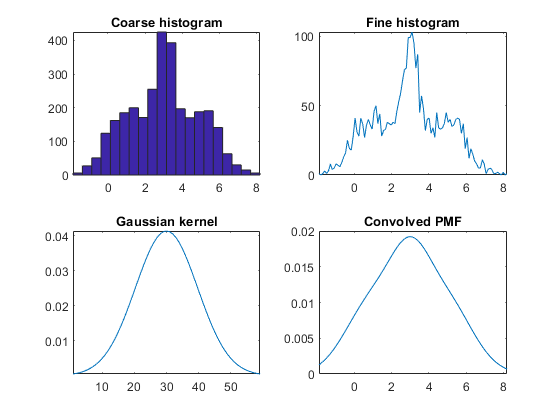

% GCK Examples


% 1D EXAMPLE
clear all
x = 0.1*[normrnd(10, 10, 1, 1000),normrnd(30, 5, 1, 1000),normrnd(50, 10, 1, 1000)];
res=[100,100];
gck1 = gckernel();
setKernel(gck1,[3,3]);
setResd(gck1,res);
gck1.setData(x,[1,0.1]); %this set smoothness of kernel in units of data. If omitted, it reverts to Bhumbra & Dyball
gck1.convolve(x);

%setResd(gck1,[100,100]);
% setKernel(gck2,[100,100]);
% setResd(gck2,[8,8]);

fh = figure;
set(fh, 'Name', '1D Gaussian convolution example')

subplot(2, 2, 1);
hist(x, 20);
ax = gca;
axis tight;
title('Coarse histogram');

subplot(2, 2, 2);
plot(gck1.xx, gck1.h);
axis tight;
title('Fine histogram');

subplot(2, 2, 3);
plot(gck1.cx);
axis tight;
%axis off;
title('Gaussian kernel');

subplot(2, 2, 4);
plot(gck1.x, gck1.p);
xlim(ax.XLim);
%axis tight;
title('Convolved PMF');

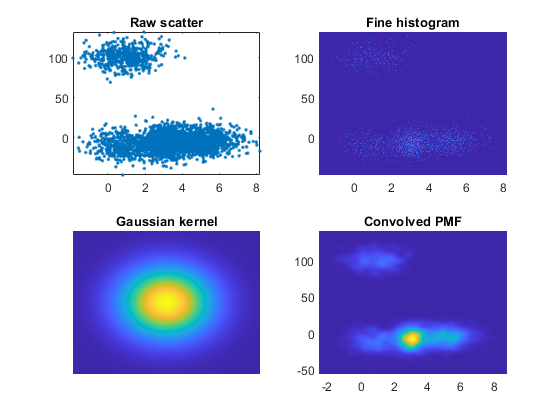


% 2D EXAMPLE

y = [x(1:500)+ normrnd(100, 10, 1, 500), x(501:3000)-normrnd(10, 10, 1, 2500)];
gck2 = gckernel();
gck1.setData([x;y],[0,0]); %this set smoothness of kernel in units of data. If omitted, it reverts to Bhumbra & Dyball
gck2.convolve([x;y]);

fh = figure();
set(fh, 'Name', '2D Gaussian convolution example')

subplot(2, 2, 1);
plot(x, y, '.');
axis tight;
title('Raw scatter');

subplot(2, 2, 2);
pcolor(gck2.xx, gck2.yy, gck2.H);
shading interp;
axis tight;
title('Fine histogram');

subplot(2, 2, 3);
pcolor(gck2.C);
shading interp;
axis tight;
axis off;
title('Gaussian kernel');

subplot(2, 2, 4);
pcolor(gck2.x, gck2.y, gck2.P);
shading interp;
axis tight;
title('Convolved PMF');